# Lesson 10

Written by Guy Bar Yosef

## Objective

After this class, you should be able to:

- Know how to model and simulate AR, MA, and ARMA models

- Understand how to use mean squared error to evaluate a time series model

- Understand how to apply linear regression to find the coefficients of an AR model

- Use an ARMA model to predict future values of a time series

# Autoregressive (AR) Models

Autoregressive models, also known as AR models, are very common for representing stochastic processes which simulate time series (data that is ordered over time). 

An AR model of order *p *looks like:


$$r(t) = \delta + \alpha_1r(t-1) + \alpha_2r(t-2) + \cdots + \alpha_pr(t-p) + v_t \\
X(t) = \delta + \sum_{n = 1}^{p}\alpha_nr(t-n) + v_t$$


where $\delta$ is a constant, $\alpha_i \ \forall \ 1 \le i \le p$ are the AR coefficients, and $v_k$ is the error term at time $t$ (whatever the value needs to be in order to 'make the model work'. We will make the common assumption that this error term is gaussian white noise with mean 0 and variance 1.

Because there exists as linear dependence between the terms of $r$, we can build linear models to forcast future values of $r$. We will see examples of this later.

Let's generate a fictional stock by choose an arbitrary AR model of order 2:

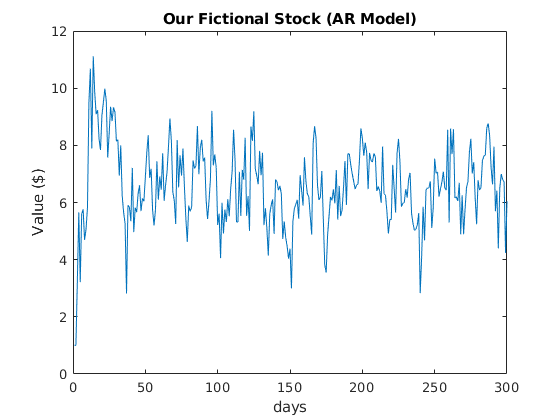

N = 300;
p = 2;
delta = 2;
alpha1 = 0.5;
alpha2 = 1/5;

alpha = [alpha2, alpha1];

r = ones(N, 1);
for i = p+1:N % note that we have to start p elements into the series
    r(i) = delta + alpha*r(i-p:i-1) + randn(1);
end

figure
plot(r)
xlabel('days'), ylabel('Value ($)'), title('Our Fictional Stock (AR Model)')

# MA Models

 We have gone over AR models above, where we use a linear combination of the past values of a signal, along with some noise term, to model/predict/forcast the current value of the signal. Moving-Average models are similar in that they also model the current value of some signal, yet instead of taking a linear combination of past values of that same signal, they take a linear combination of some random terms. This looks like:


$$r(t) =  \mu + v(t) +  \beta_1v(t-1) + \beta_2v(t-2) + \cdots + \beta_pv(t-p)\\
r(t) = \mu + v(t) + \sum_{n = 1}^{p}\beta_nv(t-n)$$


Where $\mu$ is the $r$'s expectation(its mean), the $v_i$s are random terms (often times gaussian white noise terms), and $\beta_i$s are the weights associated with each error term.

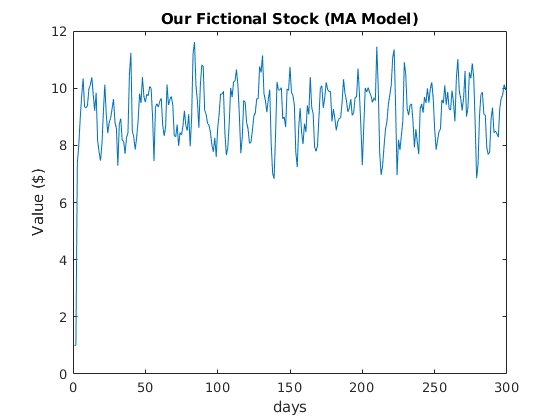

v = 2 + randn(1,N)*0.75; % our random terms
mu = 5;
beta1 = 0.8;
beta2 = 0.3;

beta = [beta2, beta1, 1];

r = ones(N,1);
for i = 1+p:N  % note that we again start after p elements in the v vector
    r(i) = mu + beta*v(i-p:i)';
end

figure
plot(r)
xlabel('days'), ylabel('Value ($)'), title('Our Fictional Stock (MA Model)')

Due to an indirect dependence between $r$ terms, we cannot linearily model the MA coefficients (the $\beta$s) as is possible with the AR coefficients. Rest assured however that it can be done. 

# ARMA Models

ARMA models, which stand for Autoregressive–Moving-Average Models,  combines AR and MA models.

An ARMA model of order $p$ looks like:


$$r(t) = \delta + v(t) + \sum_{n=1}^{p}\beta_nv(t-n) + \sum_{n=1}^{p}\alpha_nr(t-n)$$


Lets see a simulation of this if we combine the 2 simulated models above:

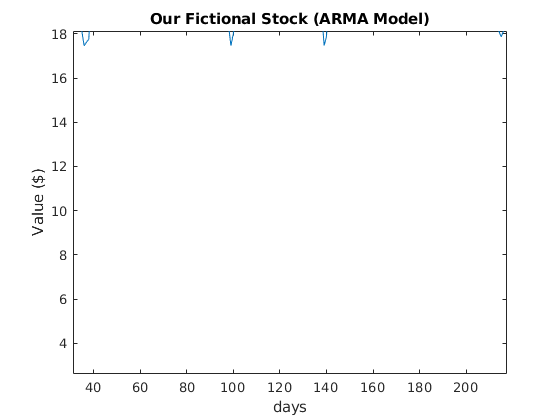

r = ones(N,1);
for i = 1+p:N  % note that we again start after p elements in the v vector
    r(i) = delta + beta*v(i-p:i)' + alpha*r(i-p:i-1);
end

figure
plot(r)
xlabel('days'), ylabel('Value ($)'), title('Our Fictional Stock (ARMA Model)')

**NOTE: **The graphs we get from the three simulations above should not be thought of as what to expect from these three types of models (AR, MA, and ARMA), but rather only as examples of how to simulate using these three models. 

**NOTE:** ARMA does NOT model definitely better than AR or MA, and at different situations one of these three may be better than the others.

# Mean Squared Error

 In order to be able to select one type of model to model a time series, we would like to have some way to evaluate how 'good' our model is. Among the most popular evaluation metric we can use is called the **Mean Squared Error (MSE). **The mean squared error is the sum of the all the squared distances between the actual point and the value the model assigns to the point. 


$$MSE = \frac{1}{n}\sum_{k = 1}^{n}\big(Y_k-\hat{Y}_k\big)^2$$


Where $Y_k
$ is the k-th point in the actual time series and $\hat{Y}_k
$ is the model's prediction of that point.

For example, if we had a time series with values $y = [3,\ 4,\ 6,\ 5]$ and 2 different models, one which approximates the values to be  $\hat{y}_1 = [2.5,\ 4.2 ,\ 5.2,\ 5.3]$ and another which approximates the values to be: $\hat{y}_2 = [4.5,\ 6,\ 5.5,\ 4]$.

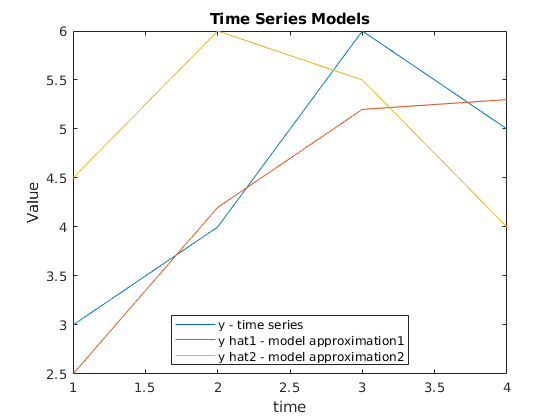

y = [3,4,6,5];
y_hat1 = [2.5, 4.2, 5.2, 5.3];
y_hat2 = [4.5, 6, 5.5, 4];

figure
plot(y, 'DisplayName', 'y - time series')
hold on
plot(y_hat1, 'DisplayName', 'y hat1 - model approximation1')
plot(y_hat2, 'DisplayName', 'y hat2 - model approximation2')
xlabel('time'), ylabel('Value'), title('Time Series Models')
legend('Location', 'best')

Lets use the mean squared error evaluation metric to decide which model is more accurate:

mse1 = mean((y-y_hat1).^2)

mse1 = 0.2550

mse2 = mean((y-y_hat2).^2)

mse2 = 1.8750

# Linear Regression

Linear regression is perhaps the most fundamental statistical tool used to model and predict data. The most popular method used for linear regression is least-squares.

Bringing us back to our problem at hand, given a time series we can use linear regression to find the optimal AR coefficients for predicting the series. What this means is that we can use linear regression to get the AR model that most closely approximates the time series, allowing us to predict its future values in the most accurate way.

So as to keep the focus on MATLAB and away from fun statistics, we skip assumptions, set-up, and proofs and instead skip right ahead to the relevant result. Given the following output, input and weight notation:


$$Output: Y = \pmatrix{y_1 &\cr y_2 \cr \vdots \cr
y_N}, \qquad 

Input: X = \pmatrix{x_{11} & x_{12} & \cdots & x_{1p} \cr x_{21} & x_{22} & \cdots & x_{2p} \cr \vdots & \vdots & \ddots & \vdots \cr x_{N1} & x_{N2} & \cdots & x_{Np} } , \qquad

Weights: \beta = \pmatrix{w_1 \cr w_2 \cr \vdots \cr w_p}$$


We can find the weights, or AR coefficients, using the following formula:


$$\beta = (X^TX)^{-1}X^TY$$


Let's hope to it then!

% Note that to fit the time series into our AR model of order p, we will lose
% p steps of our model (can be thought of as the initial values to get the
% AR model up and running).

x = zeros(N-p,p); 

x(:,1) = r(1:end-p);
x(:,2) = r(2:end-1);

y = r(1+p:end);

b = inv(x'*x)*x'*y

b =    -0.4723
    1.4719


### Time-Series Forcasting

Time series forecasting is the action of using a model to predict future values of the time series using the previously observed data. This allows all sorts of useful insights, such as predicting future stock movements, the load on a server, the population of NYC, and much much more. 

### In General

Time series are very important, whether it be for signal processing or machine learning. As such there is much research being invested into different modeling and forcasting methods. This lesson is simply a short overview to get you familiar with the topic and some of the more common buzzwords associated with it.

**Be Careful!**

In order to do any time series analysis on a time series, we must make sure it is both ergodic and stationary! Here is a link for more informaiton: https://en.wikipedia.org/wiki/Stationary_ergodic_process